clear all
clc

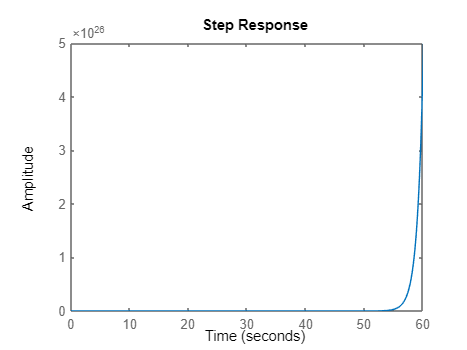

% given state-space model:
A = [ -5, -2; -3 0];
B = [ 1; -3];
C = [1, -1];
D = 0;
%checking observability
N = obsv(A,C); 
%checking controllability
[Af, Bf, Cf] = ctrbf(A,B,C); %unstable pole p=1 is controllable
controllable_poles = eig(Af(2,2));
%applying Ackerman's formula to design variable feedback controller
char_eqn = [ 1, 16, 60];
desired_poles = roots(char_eqn);
L = acker( A', C', desired_poles);
hfl = L'*C;
Areg = minus(A, hfl);
Breg = B;
Creg = C;
Dreg = D;
%converting stabilized system to transfer function form
[numreg, denreg] = ss2tf(Areg, Breg, Creg, Dreg);
G2 = tf(numreg, denreg);
%information about initial system
rank_of_N = rank(N);
order_of_sys = length(A);
[num,den] = ss2tf(A,B,C,D);
G1 = tf(num,den);
figure()
step(G1);

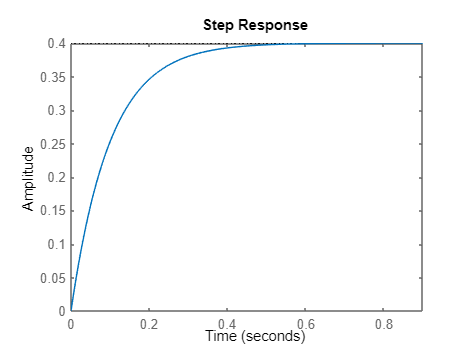

%information about stabilized system
figure()
step(G2);

In this example we have applied Ackerman's formula to create a variable feedback controller used to move the controllable unstable pole at p=1 to a desired stable pole p=-10. As shown on the 2nd step response polot, the system is now stable. We did not have to move the 2nd stable pole located at p=-6 to obtain stability. 